# **Hand Tracking**

%%% Load handimage from a url 

url_img = 'http://apmonitor.com/pds/uploads/Main/hands.jpg';
outfilename = websave('hands.jpg',url_img)

outfilename = 'C:\Users\seant\MATLAB\hands.jpg'

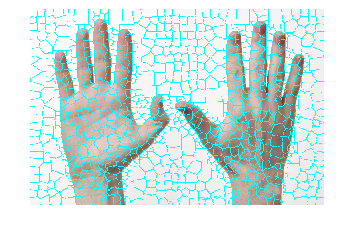


%%Read Image 
I = imread('hands.jpg');
 [L,N] = superpixels(I,1000); BW = boundarymask(L); 
 imshow(imoverlay(I,BW,'cyan'),'InitialMagnification',100);

  
figure
% Define centroid 

%%Binarize 
Ibw = imbinarize(I);

%%Fill in holes in binarized image
Ibw = imfill(Ibw,'holes');
%%%Convert binary into logical array
Ilabel = logical(Ibw);
%%% calculate coordinates for X & Y centroids
stat = regionprops(Ilabel,'centroid');

%%%Computes superpixels for the image
[L,N] = superpixels(I,500)

L =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1   

N = 430

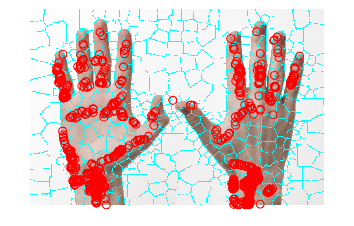

%%%%compute region boundaries for the input binary image
BW = boundarymask(L);
imshow(imoverlay(I,BW,'cyan'),'InitialMagnification',100);  hold on;
for x = 1: numel(stat)
    plot(stat(x).Centroid(1),stat(x).Centroid(2),'ro');
end

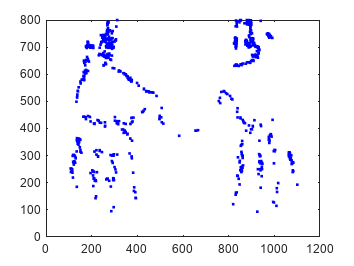

%%%TODO: Is it possible to draw a line between the dots? 
figure
for x = 1: numel(stat)
    plot(stat(x).Centroid(1),stat(x).Centroid(2),'.b-');
    drawnow;
    hold on;
end